# Root Finding - IC Activity 9.16

## Bungee Jump

Graphically find the root of the bungee jumper velocity @ time t = 4 for masses of 50 kg to 200 kg. Find which mass is at terminal velocity if the initial velo was 36 m/s and the coefficient of drag is 0.25.

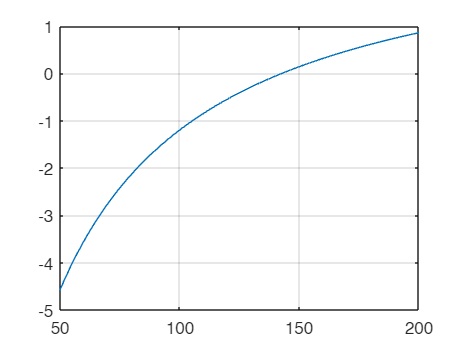

clear; clc;
cd = 0.25; g = 9.81; v = 36; t = 4;
mp = linspace(50,200); % mass of person
fp = sqrt(g*mp/cd).*tanh(sqrt(g*cd./mp)*t)-v;
plot(mp,fp),grid;


% Best guess of root: ~ 145 kg
% Check: (should be about 0)
fp = sqrt(g*145/cd).*tanh(sqrt(g*cd./145)*t)-v

fp = 0.0456

#### Bisection

% Number of iterations required
numItr = ceil(log2((max(mp)-min(mp))/0.0001)) %0.0001 is abolute error here, not rel

numItr = 21

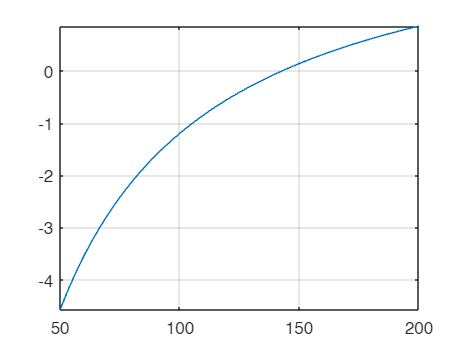


% Way 1
func = @(m) sqrt(g.*m./cd).*tanh(sqrt(g.*cd./m).*t) - v;
fplot(func, [50 200]),grid

x1 = 50; xu = 200; maxit = 50; es = 0.0001; % rel er
[root,relErr,iter] = bisect(func,x1,xu,es,maxit) 

root = 142.7377

fx = 1.3388e-06

relErr = 5.0110e-05

iter = 21


% Pass parameters in another way
fm = @(m,cd,t,v) sqrt(g.*m./cd).*tanh(sqrt(9.81.*cd./m).*t) - v;
[root,relErr,iter] = bisect(@(m) fm(m,0.25,4,36),x1,xu,es,maxit)

root = 142.7377

fx = 1.3388e-06

relErr = 5.0110e-05

iter = 21

#### Random Incremental Search Method

xb = incsearch(func,x1,xu,1000) % can find multiple roots

number of root brackets:
     1



xb =   142.6426  142.7928
